# 随机信号噪声功率谱密度分析

本文件主要尝试探讨如何针对一段噪声信号进行功率谱密度、噪声带宽等参数的计算和分析，本模块采用的数据主要是由Simulink中的有限带宽白噪声模块产生的一段噪声数据，因此文件夹下存在两个与本文件同名的文件，分别用于产生噪声和保存噪声。

% 此处导入一段噪声数据, 可以是 simulink 生成的或者导入 mat 文件
% 注意如果此处不导入噪声数据则无法进行后续分析

% 导入噪声数据
load('NoiseBandWidthAnalysis.mat');
% % 记录原始白噪声数据
% Data=out.ScopeData(:,2);

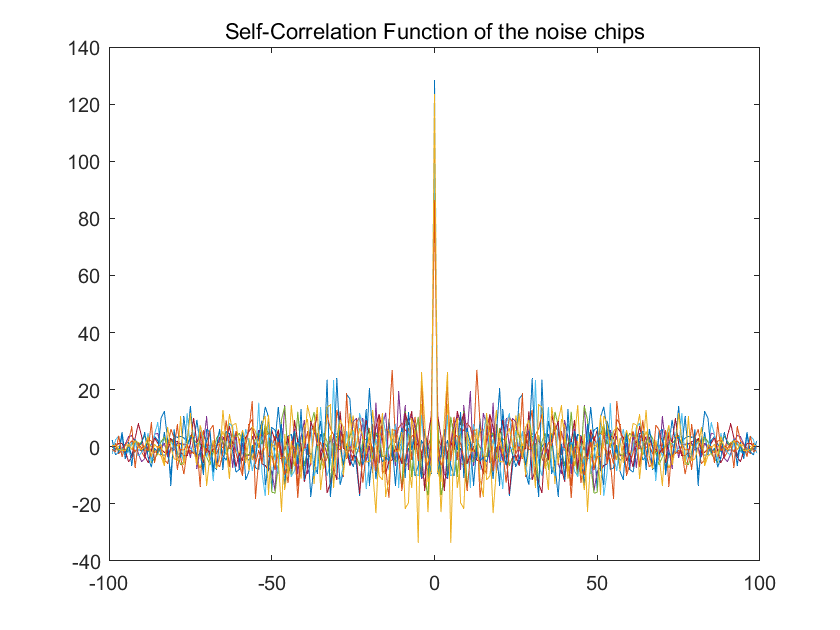

% 把原始数据平均拆成 10 段
SampleData=zeros(10,100);
for index=1:10
    SampleData(index,:)=Data((index-1)*100+1:index*100,1);
end
% 分别求这 10 段数据的相关函数
SampleCorr=zeros(10,199);
for index=1:10
    SampleCorr(index,:)=xcorr(SampleData(index,:));
end
plot(-99:99,SampleCorr);title('Self-Correlation Function of the noise chips');

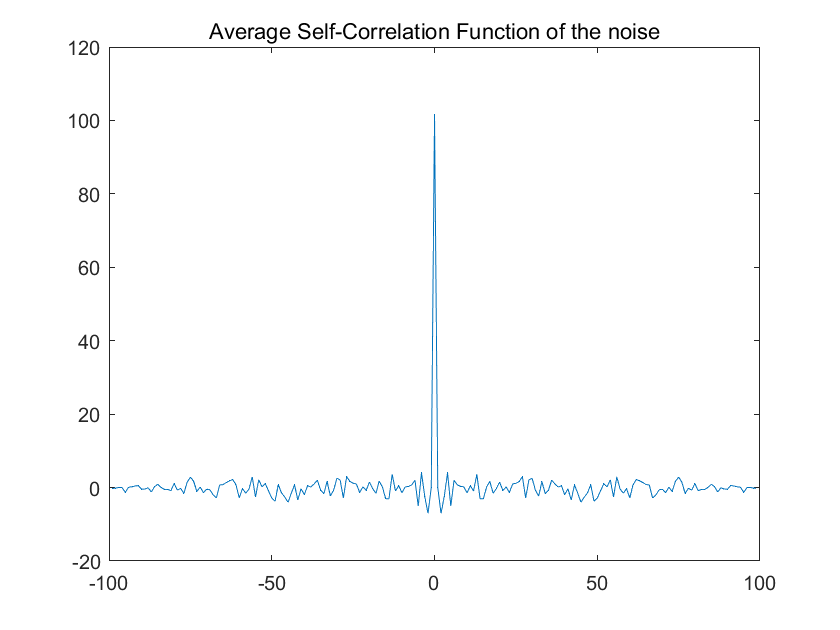

% 求取平均相关函数
AverageCorr=0.1*ones(1,10)*SampleCorr;
plot(-99:99,AverageCorr);title('Average Self-Correlation Function of the noise');

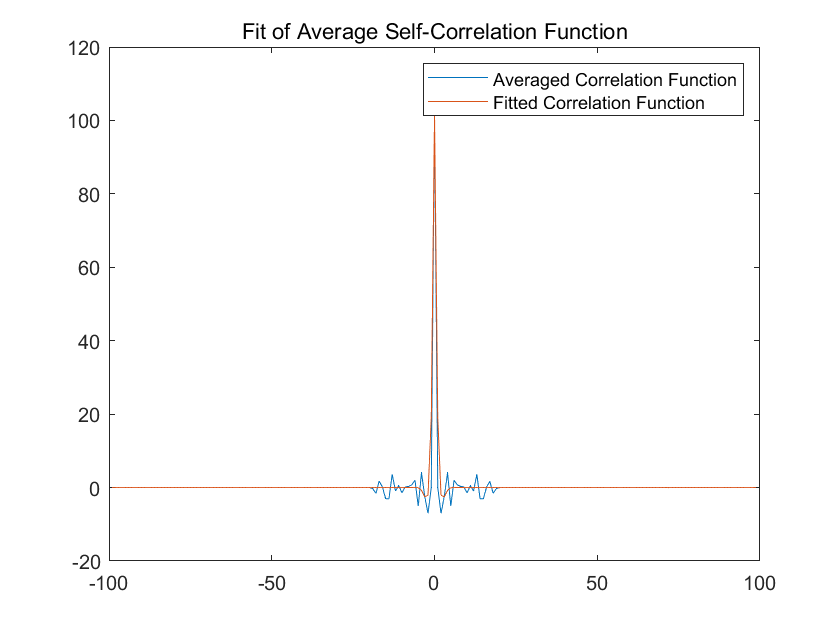

% 截断, 拟合
TruncateLength=20; % 截断长度
TruncatedAverageCorr=AverageCorr;
TruncatedAverageCorr(1,100+TruncateLength:199)=...
    zeros(1,99-TruncateLength+1);
TruncatedAverageCorr(1,1:100-TruncateLength)=...
    zeros(1,99-TruncateLength+1);
A=TruncatedAverageCorr(1,100);           % 拟合函数幅值
w=0.9;                                   % 拟合函数振荡频率
alpha=1.2;                               % 拟合函数衰减速率
fit=@(t) A*cos(w*t).*exp(-alpha*abs(t)); % 拟合函数
n=-99:99;FittedCorr=fit(n);
plot(n,TruncatedAverageCorr,n,FittedCorr);
title('Fit of Average Self-Correlation Function');
legend('Averaged Correlation Function',...
    'Fitted Correlation Function');

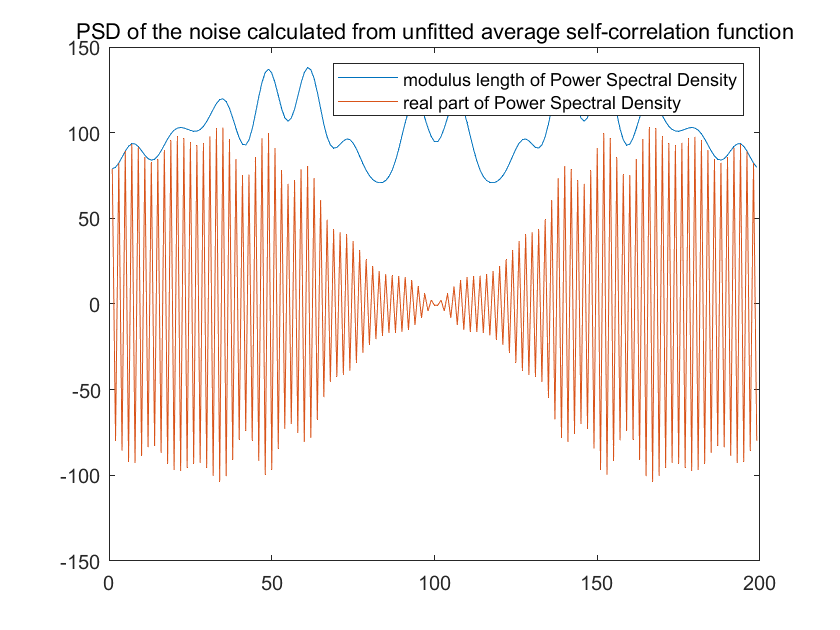

% 用截断后未拟合的相关函数求傅里叶变换(答案是寄)
AveragePSD=fft(TruncatedAverageCorr);f=1:199;
plot(f,abs(AveragePSD),f,real(AveragePSD));
title(['PSD of the noise calculated from ' ...
    'unfitted average self-correlation function']);
legend('modulus length of Power Spectral Density',...
    'real part of Power Spectral Density');

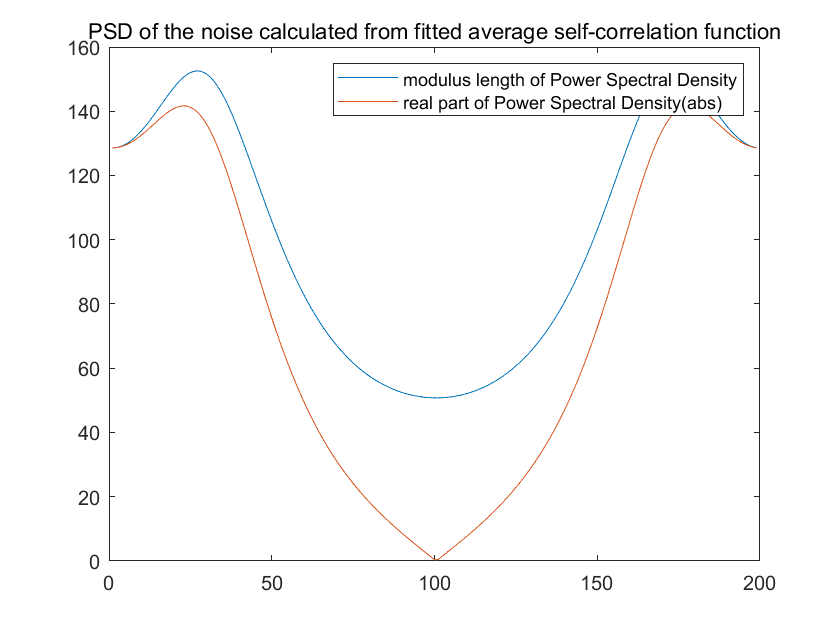

% 用拟合函数作为相关函数求傅里叶变换
FittedPSD=fft(FittedCorr);
plot(f,abs(FittedPSD),f,abs(real(FittedPSD)));
title(['PSD of the noise calculated from ' ...
    'fitted average self-correlation function']);
legend('modulus length of Power Spectral Density',...
    'real part of Power Spectral Density(abs)');

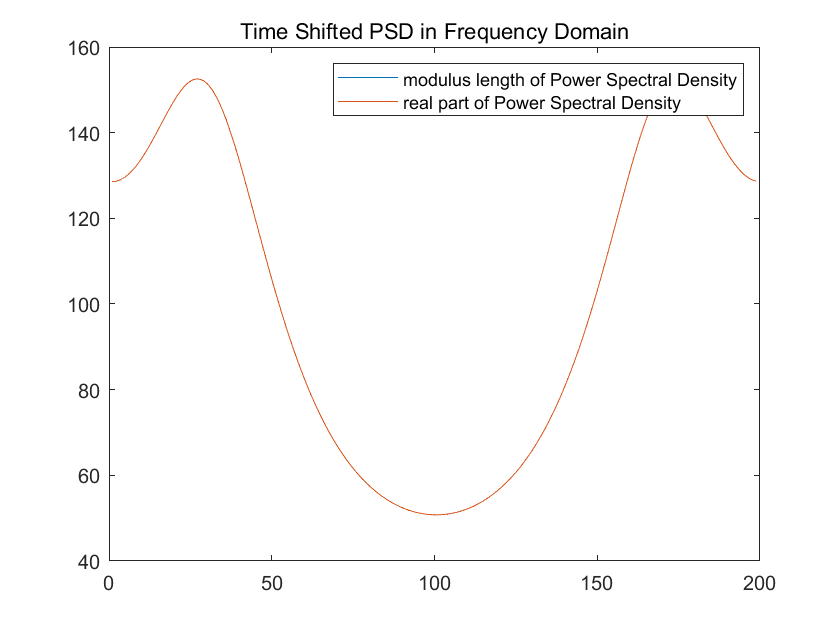

% 将傅里叶变换以后的结果用时移性质使得
% 用于傅里叶变换的相关函数是一个实偶函数
TranslatedPSD=FittedPSD.*exp(2*pi*1i*(0:198)*(-100)/199);
plot(f,abs(TranslatedPSD),f,real(TranslatedPSD));
title('Time Shifted PSD in Frequency Domain');
legend('modulus length of Power Spectral Density',...
    'real part of Power Spectral Density');

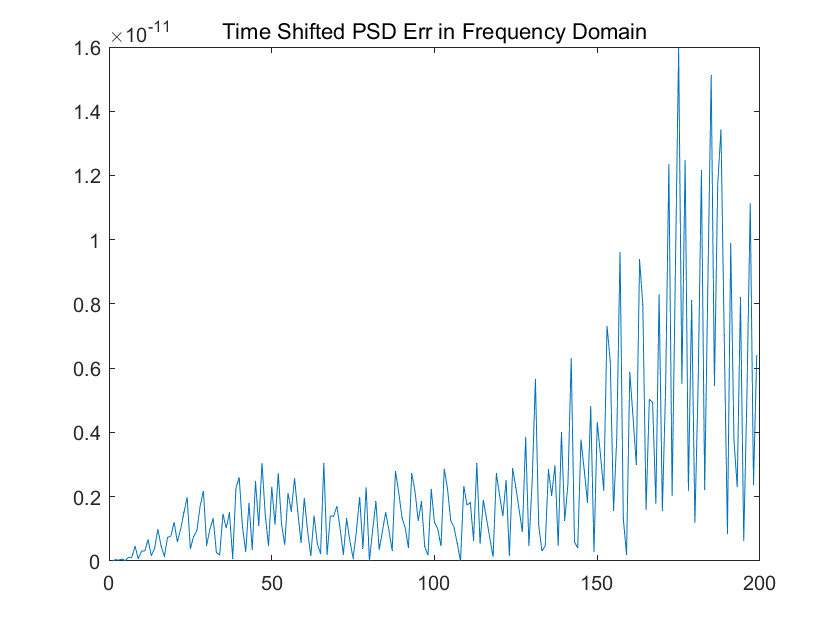

plot(f,abs(imag(TranslatedPSD)));title('Time Shifted PSD Err in Frequency Domain');

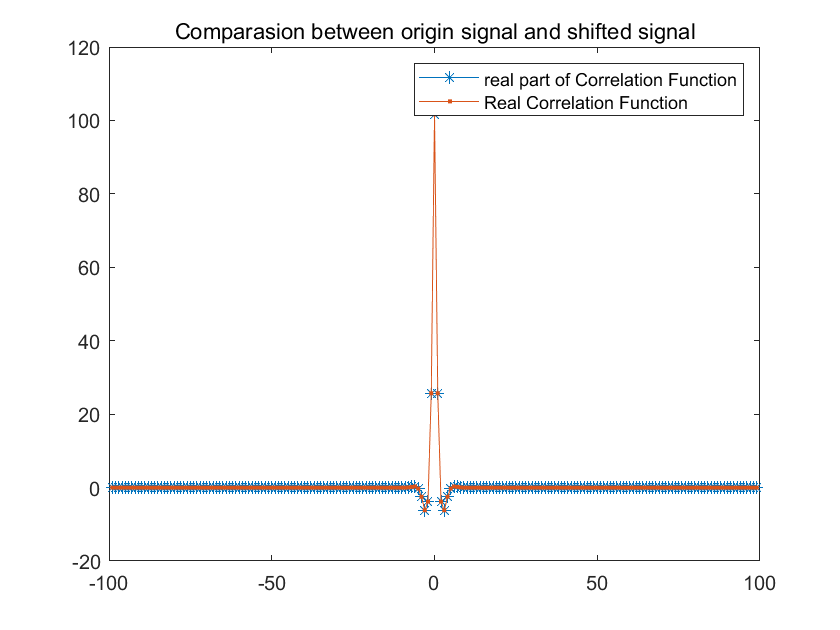

ifft_corr=ifft(TranslatedPSD); % 把功率谱密度信号变换回相关函数
plot(n,real(circshift(ifft_corr,99)),'*-',n,FittedCorr,'.-');
title('Comparasion between origin signal and shifted signal');
legend('real part of Correlation Function','Real Correlation Function');

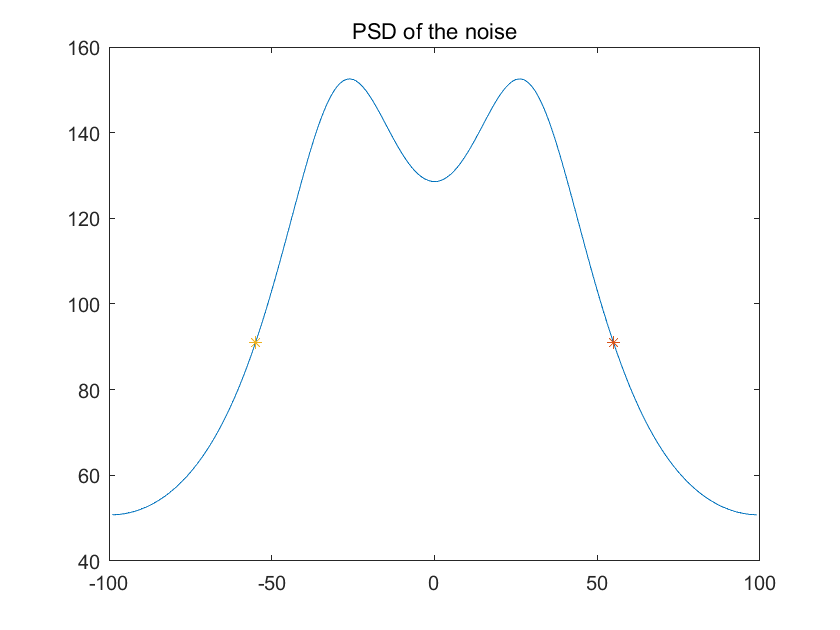

% 将计算出来的模长认为是实际功率谱密度
RealUsedPSD=circshift(abs(FittedPSD),99);
% 遍历求出功率谱密度等于零频值 0.707 处的频率
pos = 0;
for index=100:199
    if RealUsedPSD(1,index)>RealUsedPSD(1,100)/sqrt(2)
        pos=index-100;
    end
end
plot(n,RealUsedPSD);hold on;title('PSD of the noise');
plot(pos,RealUsedPSD(1,pos+100),'*');hold on;
plot(-pos,RealUsedPSD(1,pos+100),'*');hold off;

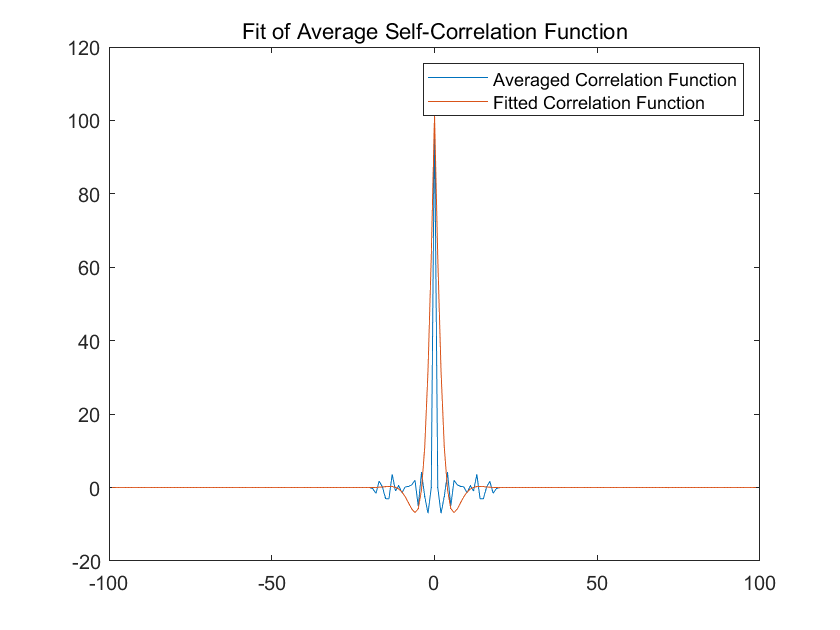

% 重新做一组拟合参数求带宽
w1=0.4;                                     % 拟合函数振荡频率
alpha1=0.4;                                 % 拟合函数衰减速率
fit1=@(t) A*cos(w1*t).*exp(-alpha1*abs(t)); % 拟合函数
FittedCorr1=fit1(n);
plot(n,TruncatedAverageCorr,n,FittedCorr1);
title('Fit of Average Self-Correlation Function');
legend('Averaged Correlation Function',...
    'Fitted Correlation Function');
FittedPSD1=fft(FittedCorr1); % 用拟合函数作为相关函数求傅里叶变换
RealUsedPSD1=circshift(abs(FittedPSD1),99);
pos1 = 0;
for index=100:199
    if RealUsedPSD1(1,index)>RealUsedPSD1(1,100)/sqrt(2)
        pos1=index-100;
    end
end
hold off;plot(n,RealUsedPSD1);hold on;title('PSD of the noise');

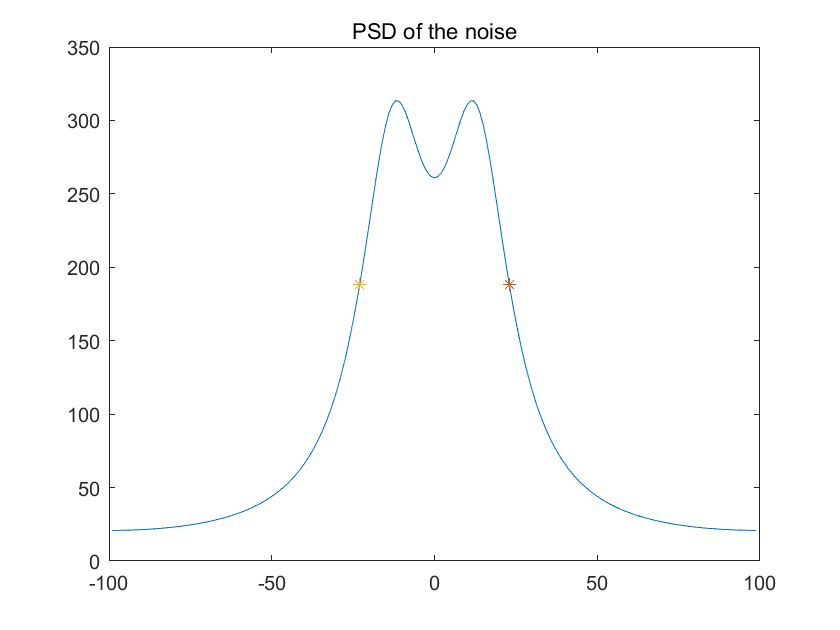

plot(pos1,RealUsedPSD1(1,pos1+100),'*');hold on;
plot(-pos1,RealUsedPSD1(1,pos1+100),'*');hold off;